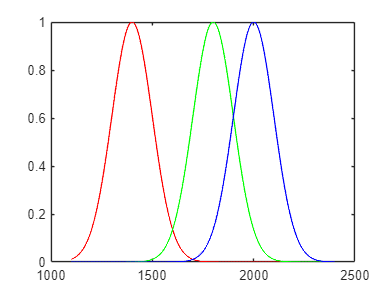

clear
clc
size_p = 128;
spec_points = 2200;
w_st = 1100;
w_en = 2400;
wl = w_st:(w_en-w_st)/spec_points:w_en;
r_w = 1400;
g_w = 1800;
b_w = 2000;
[~,r_i] = ismember(r_w,round(wl));
[~,g_i] = ismember(g_w,round(wl));
[~,b_i] = ismember(b_w,round(wl));

T(1:size_p,1:size_p,1:spec_points+1) = 1;

r_A = 1;    
g_A = 1;
b_A = 1;

r_s = r_A * exp(-(wl-r_w).^2./(2.*((100)).^2));
r_s = r_s .* (r_s>10e-5);
g_s = g_A * exp(-(wl-g_w).^2./(2.*((100)).^2));
g_s = g_s .* (g_s>10e-5);
b_s = b_A * exp(-(wl-b_w).^2./(2.*((100)).^2));
b_s = b_s .* (b_s>10e-5);
wh_s = 20+17*sin(pi*(wl-500)/800);
wh_s = (wh_s-min(wh_s))/max(wh_s-min(wh_s));

plot(wl,r_s,'LineWidth',1,'Color','R')
hold on
plot(wl,g_s,'LineWidth',1,'Color','G')
plot(wl,b_s,'LineWidth',1,'Color','B')
hold off

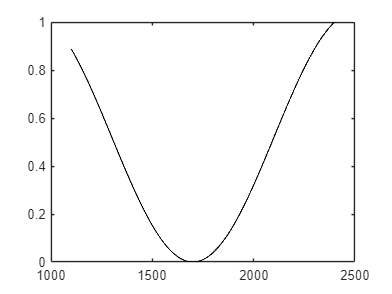

plot(wl,wh_s,'LineWidth',1,'Color','Black')

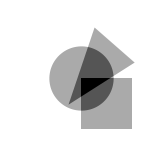


circle(1:size_p,1:size_p) = 0;
circle = im2gray(insertShape(circle,"FilledCircle", [size_p/2 size_p/2 size_p/4]))/2;
rectangle(1:size_p,1:size_p) = 0;
rectangle = im2gray(insertShape(rectangle,"FilledRectangle", [size_p/2 size_p/2 size_p/2.5 size_p/2.5]))/2;
polygon(1:size_p,1:size_p) = 0;
polygon = im2gray(insertShape(polygon,"FilledPolygon", [size_p/2-size_p/10 size_p/2+size_p/5 size_p/2+size_p/10 size_p/10 size_p-size_p/12 size_p/2-size_p/8]))/2;
imshow(1-(rectangle+circle+polygon),[]);
truesize([128 128]);

for i = 1:size_p
    for j = 1:size_p
        if circle(i,j)>0
            T(i,j,:) = squeeze(squeeze(T(i,j,:)))' .* r_s(1,:);
        end
        if rectangle(i,j)>0
            T(i,j,:) = squeeze(squeeze(T(i,j,:)))' .* g_s(1,:);
        end
        if polygon(i,j)>0
            T(i,j,:) = squeeze(squeeze(T(i,j,:)))' .* b_s(1,:);
        end
        if circle(i,j)==0 && polygon(i,j)==0 && rectangle(i,j)==0
            T(i,j,:) = 0;
        end
    end
end

N = 1000;
sI(size_p,size_p,spec_points+1) = 0;
sBI(size_p,size_p,spec_points+1) = 0;
I(size_p,size_p,spec_points+1)=0;
B_i_s(1:N,1:spec_points+1) = 0;
sB(1:spec_points+1) = 0;


for i = 1 : N
    I(:,:,:) = 0;
    seed = rand(fix(size_p/4));
    seed = double(seed>0.7);
    c = imresize(seed,size_p/length(seed),'nearest');
    for h = 1:size_p
        for w = 1:size_p
            if c(h,w)>0
                I(h,w,:) = wh_s(:);
                sI(h,w,:) = sI(h,w,:) + I(h,w,:);
            end
        end
    end
    a = I.*T;
    for s_in = 1:spec_points
        B_i_s(i,s_in) = B_i_s(i,s_in) + sum(sum(a(:,:,s_in)));
    end
    for s_in = 1:spec_points
        for h = 1:size_p
            for w = 1:size_p
                sBI(h,w,s_in) = sBI(h,w,s_in) ...
                    + I(h,w,s_in) .* B_i_s(i,s_in);
            end
        end
    end
    for s_in = 1:spec_points
        sB(s_in)= sB(s_in)+B_i_s(i,s_in);
    end
end

for i=1:spec_points+1
    G(:,:,i) = sBI(:,:,i) / N - (sB(1,i)/N) .* (sI(:,:,i)./N);
    G_f(:,:,i) = medfilt2(squeeze(G(:,:,i)),[20 20]);
end

[~,s_i] = ismember(560,round(wl));
imshow(T(:,:,s_i),[])
imshow(G_f(:,:,s_i),[])

hcube = hypercube(G_f,wl);
rgbImg = colorize(hcube,'Method','RGB');
figure
imagesc(rgbImg)
title('RGB Image of Data Cube')